## Initial Runge-Kutta 4 method

Implementation with adaptive step.

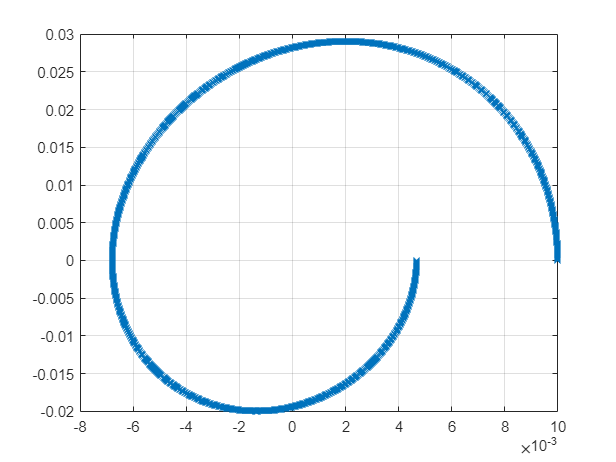

global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2

% a1=1;b1=1;c1=0;al1=0;bt1=1;
% a2=-10;b2=2.7;c2=0.4;al2=-437.5;bt2=0.003;
a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.2;c2=0.7;al2=-72-7/9;bt2=0.0015;



h=0.01;
x2=[];
T=[];
xdif=[];
j=1;
h=0.01;
for i=setdiff(1:1:1,0)
    x=[]; x(1) = i*h;
    y=[]; y(1) = 0;
    [x,y,T(j)] = RK4cycle(x,y);
    x2(j)=i*h;
    xdif(j)=x(end)-x(1);
    j=j+1;
    plot(x,y,"x");
    hold on
end
grid on
hold off

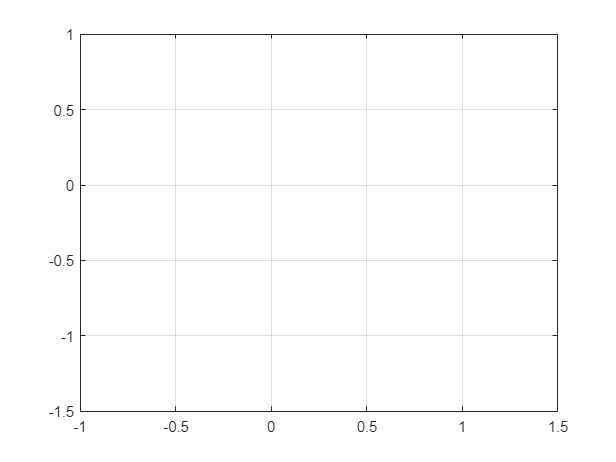

plot(x2,xdif);
grid on

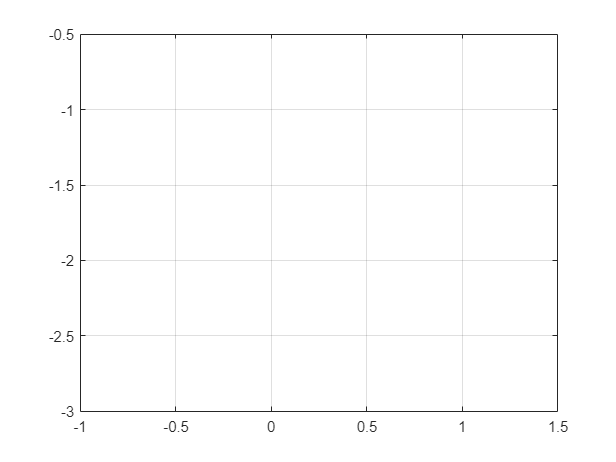

plot(x2,T);
grid on

## Functions

function [x,y,T] = RK4cycle(x,y)

    global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
    
    % ODE
    dxdt=@(t,x,y) a1*x^2 + b1*x*y + c1*y^2 + al1*x + bt1*y;
    dydt=@(t,x,y) a2*x^2 + b2*x*y + c2*y^2 + al2*x + bt2*y;
    
    % Runge-Kutta 4
    
    tprev=0.01;
    epsilon=-0.01;
%     dt = 0.001;
    dt1=@(t,x,y) max(-0.001,epsilon/(dxdt(t,x,y)^2+dydt(t,x,y)^2));
%     dt2=@(t,x,y) epsilon/(dxdt(t,x,y)^2+dydt(t,x,y)^2);

        for i=1:1:2

            dt = dt1(tprev, x(i), y(i));

            k1x=dxdt(tprev, x(i), y(i));
            k1y=dydt(tprev, x(i), y(i));
        
            k2x=dxdt(tprev+dt/2, x(i)+dt/2*k1x, y(i)+dt/2*k1y);
            k2y=dxdt(tprev+dt/2, x(i)+dt/2*k1x, y(i)+dt/2*k1y);
        
            k3x=dxdt(tprev+dt/2, x(i)+dt/2*k2x, y(i)+dt/2*k2y);
            k3y=dxdt(tprev+dt/2, x(i)+dt/2*k2x, y(i)+dt/2*k2y);
        
            k4x=dxdt(tprev+dt, x(i)+dt*k3x, y(i)+dt*k3y);
            k4y=dxdt(tprev+dt, x(i)+dt*k3x, y(i)+dt*k3y);
        
            x(i+1)=x(i) + dt/6*(k1x+2*k2x+2*k3x+k4x);
            y(i+1)=y(i) + dt/6*(k1y+2*k2y+2*k3y+k4y);
            
            tprev=tprev+dt;
        
        end

        i=3;

        while y(i)*y(i-1)>0

            dt = dt1(tprev, x(i), y(i));

            k1x=dxdt(tprev, x(i), y(i));
            k1y=dydt(tprev, x(i), y(i));
        
            k2x=dxdt(tprev+dt/2, x(i)+dt/2*k1x, y(i)+dt/2*k1y);
            k2y=dxdt(tprev+dt/2, x(i)+dt/2*k1x, y(i)+dt/2*k1y);
        
            k3x=dxdt(tprev+dt/2, x(i)+dt/2*k2x, y(i)+dt/2*k2y);
            k3y=dxdt(tprev+dt/2, x(i)+dt/2*k2x, y(i)+dt/2*k2y);
        
            k4x=dxdt(tprev+dt, x(i)+dt*k3x, y(i)+dt*k3y);
            k4y=dxdt(tprev+dt, x(i)+dt*k3x, y(i)+dt*k3y);
        
            x(i+1)=x(i) + dt/6*(k1x+2*k2x+2*k3x+k4x);
            y(i+1)=y(i) + dt/6*(k1y+2*k2y+2*k3y+k4y);
            
            tprev=tprev+dt;
            i=i+1;

        end
        
        j=i;

        for i=i:1:i+2

            dt = dt1(tprev, x(i), y(i));

            k1x=dxdt(tprev, x(i), y(i));
            k1y=dydt(tprev, x(i), y(i));
        
            k2x=dxdt(tprev+dt/2, x(i)+dt/2*k1x, y(i)+dt/2*k1y);
            k2y=dxdt(tprev+dt/2, x(i)+dt/2*k1x, y(i)+dt/2*k1y);
        
            k3x=dxdt(tprev+dt/2, x(i)+dt/2*k2x, y(i)+dt/2*k2y);
            k3y=dxdt(tprev+dt/2, x(i)+dt/2*k2x, y(i)+dt/2*k2y);
        
            k4x=dxdt(tprev+dt, x(i)+dt*k3x, y(i)+dt*k3y);
            k4y=dxdt(tprev+dt, x(i)+dt*k3x, y(i)+dt*k3y);
        
            x(i+1)=x(i) + dt/6*(k1x+2*k2x+2*k3x+k4x);
            y(i+1)=y(i) + dt/6*(k1y+2*k2y+2*k3y+k4y);
            
            tprev=tprev+dt;
        
        end
        
        i=j+2;

        while y(i)*y(i-1)>0

            dt = dt1(tprev, x(i), y(i));

            k1x=dxdt(tprev, x(i), y(i));
            k1y=dydt(tprev, x(i), y(i));
        
            k2x=dxdt(tprev+dt/2, x(i)+dt/2*k1x, y(i)+dt/2*k1y);
            k2y=dxdt(tprev+dt/2, x(i)+dt/2*k1x, y(i)+dt/2*k1y);
        
            k3x=dxdt(tprev+dt/2, x(i)+dt/2*k2x, y(i)+dt/2*k2y);
            k3y=dxdt(tprev+dt/2, x(i)+dt/2*k2x, y(i)+dt/2*k2y);
        
            k4x=dxdt(tprev+dt, x(i)+dt*k3x, y(i)+dt*k3y);
            k4y=dxdt(tprev+dt, x(i)+dt*k3x, y(i)+dt*k3y);
        
            x(i+1)=x(i) + dt/6*(k1x+2*k2x+2*k3x+k4x);
            y(i+1)=y(i) + dt/6*(k1y+2*k2y+2*k3y+k4y);
            
            tprev=tprev+dt;
            i=i+1;

        end
        T=tprev;
end